% Initialiser
clear; clc;

% Gitte verdier fra oppgaven
top_dB = 12; % Toppverdi i dB
resonance_freq = 10^(0.8); % Resonansfrekvens fra diagrammet
start_dB = -8; % Startverdi i dB

% Beregn toppforsterkning (absoluttverdi)
top_gain = 10^(top_dB / 20);
fprintf('Toppforsterkning (absolutt): %.3f\n', top_gain);

Toppforsterkning (absolutt): 3.981



% Symbolsk variabel for zeta
syms zeta

% Sett opp ligningen for toppforsterkningen
top_gain_eq = 1 / (2 * zeta * sqrt(1 - zeta^2));

% Løs likningen for zeta
zeta_solutions = double(solve(top_gain_eq == top_gain, zeta));

% Velg den laveste (gyldige) verdien for zeta
zeta_val = min(zeta_solutions(zeta_solutions > 0 & zeta_solutions < 1));
fprintf('Valgt dempningsfaktor zeta = %.3f\n', zeta_val);

Valgt dempningsfaktor zeta = 0.127



% Beregn naturlig frekvens omega_n
omega_n = resonance_freq / sqrt(1 - 2 * zeta_val^2);
fprintf('Naturlig frekvens omega_n = %.3f rad/s\n', omega_n);

Naturlig frekvens omega_n = 6.413 rad/s



% Beregn DC-forsterkningen K
K = 10^(start_dB / 20);
fprintf('DC-forsterkning K = %.3f\n', K);

DC-forsterkning K = 0.398



% Sett opp overføringsfunksjonen
s = tf('s');
H = K * omega_n^2 / (s^2 + 2 * zeta_val * omega_n * s + omega_n^2)

H =
 
          16.37
  ---------------------
  s^2 + 1.624 s + 41.13
 
Continuous-time transfer function.
Model Properties



% Vis transferfunksjonen
%fprintf('Overføringsfunksjon G(s):\n');

Overføringsfunksjon G(s):


%disp(H);

  tf with properties:

       Numerator: {[0 0 16.3739]}
     Denominator: {[1 1.6240 41.1294]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



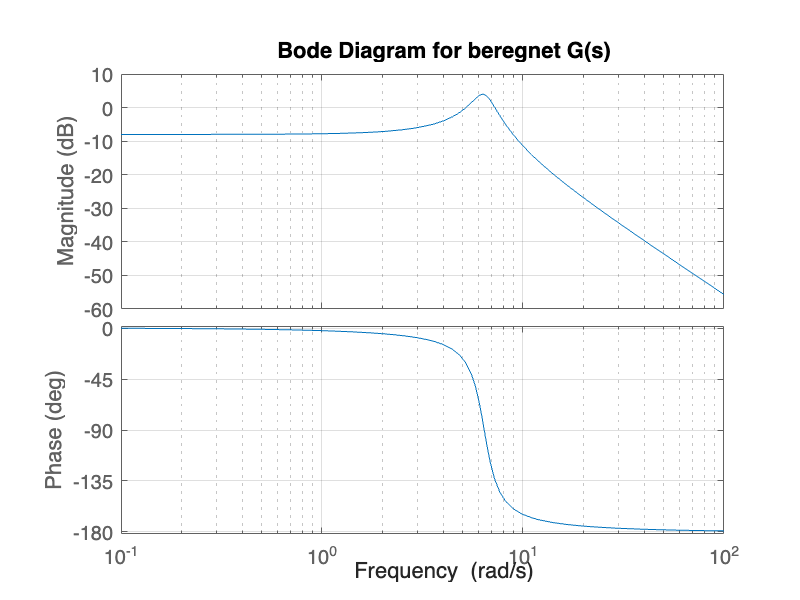


% Plot Bode-diagrammet
figure;
bode(H);
grid on;
title('Bode Diagram for beregnet G(s)');